**Exercise 1-6. **This exercise will test the concept of condition number. We will test the accuracy of solving Ax = b when noise is added to b for matrices A with different condition numbers. 

(a) To build the two matrices, generate a random U ∈ R100×100 and V ∈ R100×100 and then create two Σ matrices: the first Σ will have singular values spaced logarithmically from 100 to 1, and the second Σ will have singular values spaced logarithmically from 100 to 10^−6. Use these matrices to create two A matrices, one with a condition number of 100 and the other with a condition number of 100 million. Now create a random b vector, solve for x using the two methods, and compare the results. Add a small ε to b, with norm 10^−6 smaller than the norm of b. Now solve for x using this new b + ε and compare the results. 						

% Define matrix dimensions
n = 100;

% Generate random matrices U and V
U = randn(n);
V = randn(n);

% Perform QR factorization to get orthogonal matrices
[U, ~] = qr(U);
[V, ~] = qr(V);

% Create Σ matrices with logarithmic spacing
sigma1 = logspace(log10(100), log10(1), n);         % Singular values for condition number 100
sigma2 = logspace(log10(100), log10(1e-6), n);      % Singular values for condition number 1e8

% Create diagonal Σ matrices
Sigma1 = diag(sigma1);
Sigma2 = diag(sigma2);

% Construct matrices A1 and A2
A1 = U * Sigma1 * V';   % Matrix with condition number 100
A2 = U * Sigma2 * V';   % Matrix with condition number 1e8

% Create a random b vector
b = randn(n, 1);

% Solve Ax = b for both A1 and A2
x1 = A1 \ b;
x2 = A2 \ b;

% Add a small epsilon to b (epsilon norm is 1e-6 smaller than norm(b))
epsilon = 1e-6 * norm(b) * randn(n, 1);
b_epsilon = b + epsilon;

% Solve for x using b + epsilon
x1_epsilon = A1 \ b_epsilon;
x2_epsilon = A2 \ b_epsilon;

% Compare the solutions before and after adding epsilon
error1 = norm(x1 - x1_epsilon) / norm(x1);
error2 = norm(x2 - x2_epsilon) / norm(x2);

% Display results
fprintf('Condition number of A1 (approximately 100):\n');

Condition number of A1 (approximately 100):


fprintf(['Error in solution after perturbing b: %.3e\n'], error1);

Error in solution after perturbing b: 9.757e-06


fprintf('\n');

fprintf('Condition number of A2 (approximately 1e8):\n');

Condition number of A2 (approximately 1e8):


fprintf('Error in solution after perturbing b: %.3e\n', error2);

Error in solution after perturbing b: 9.513e-06


b)  Now repeat the experiment above with many different noise vectors ε and compute the distribution of the error; plot this error as a histogram and explain the shape. 	

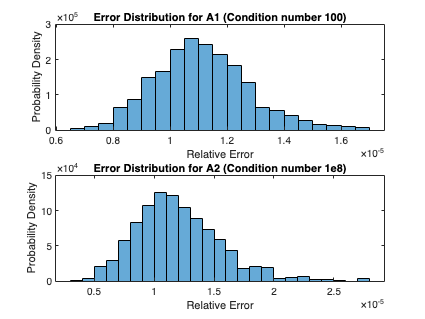

% Define matrix dimensions
n = 100;
num_trials = 1000;  % Number of trials for different noise vectors

% Generate random matrices U and V
U = randn(n);
V = randn(n);

% Perform QR factorization to get orthogonal matrices
[U, ~] = qr(U);
[V, ~] = qr(V);

% Create Σ matrices with logarithmic spacing
sigma1 = logspace(log10(100), log10(1), n);         % Singular values for condition number 100
sigma2 = logspace(log10(100), log10(1e-6), n);      % Singular values for condition number 1e8

% Create diagonal Σ matrices
Sigma1 = diag(sigma1);
Sigma2 = diag(sigma2);

% Construct matrices A1 and A2
A1 = U * Sigma1 * V';   % Matrix with condition number 100
A2 = U * Sigma2 * V';   % Matrix with condition number 1e8

% Create a random b vector
b = randn(n, 1);

% Solve Ax = b for both A1 and A2
x1 = A1 \ b;
x2 = A2 \ b;

% Initialize arrays to store the errors
errors1 = zeros(num_trials, 1);
errors2 = zeros(num_trials, 1);

% Loop through multiple trials to compute error distribution
for i = 1:num_trials
    % Generate a small epsilon (norm is 1e-6 smaller than norm(b))
    epsilon = 1e-6 * norm(b) * randn(n, 1);
    b_epsilon = b + epsilon;
    
    % Solve for x using b + epsilon
    x1_epsilon = A1 \ b_epsilon;
    x2_epsilon = A2 \ b_epsilon;
    
    % Compute relative error for each condition number
    errors1(i) = norm(x1 - x1_epsilon) / norm(x1);
    errors2(i) = norm(x2 - x2_epsilon) / norm(x2);
end

% Plot histograms of the error distributions
figure;
subplot(2,1,1);
histogram(errors1, 'Normalization', 'pdf');
title('Error Distribution for A1 (Condition number 100)');
xlabel('Relative Error');
ylabel('Probability Density');

subplot(2,1,2);
histogram(errors2, 'Normalization', 'pdf');
title('Error Distribution for A2 (Condition number 1e8)');
xlabel('Relative Error');
ylabel('Probability Density');

(c)  Repeat the above experiment comparing two A matrices with different singular value distributions: the first Σ will have values spaced linearly from 100 to 1 and the second Σ will have value spaced logarithmically from 100 to 1. Does anything change? Please explain why yes or no. 

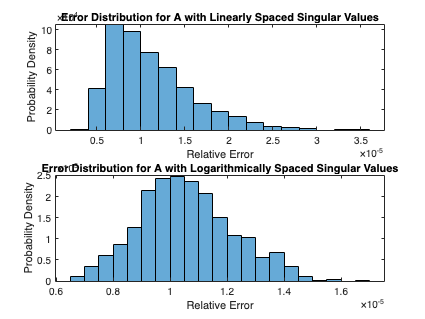

% Define matrix dimensions
n = 100;
num_trials = 1000;  % Number of trials for different noise vectors

% Generate random matrices U and V
U = randn(n);
V = randn(n);

% Perform QR factorization to get orthogonal matrices
[U, ~] = qr(U);
[V, ~] = qr(V);

% Create Σ matrices: one with linear spacing, one with logarithmic spacing
sigma_linear = linspace(100, 1, n);         % Singular values spaced linearly from 100 to 1
sigma_log = logspace(log10(100), log10(1), n);  % Singular values spaced logarithmically from 100 to 1

% Create diagonal Σ matrices
Sigma_linear = diag(sigma_linear);
Sigma_log = diag(sigma_log);

% Construct matrices A_linear and A_log
A_linear = U * Sigma_linear * V';  % Matrix with linearly spaced singular values
A_log = U * Sigma_log * V';        % Matrix with logarithmically spaced singular values

% Create a random b vector
b = randn(n, 1);

% Solve Ax = b for both A_linear and A_log
x_linear = A_linear \ b;
x_log = A_log \ b;

% Initialize arrays to store the errors
errors_linear = zeros(num_trials, 1);
errors_log = zeros(num_trials, 1);

% Loop through multiple trials to compute error distribution
for i = 1:num_trials
    % Generate a small epsilon (norm is 1e-6 smaller than norm(b))
    epsilon = 1e-6 * norm(b) * randn(n, 1);
    b_epsilon = b + epsilon;
    
    % Solve for x using b + epsilon
    x_linear_epsilon = A_linear \ b_epsilon;
    x_log_epsilon = A_log \ b_epsilon;
    
    % Compute relative error for each matrix
    errors_linear(i) = norm(x_linear - x_linear_epsilon) / norm(x_linear);
    errors_log(i) = norm(x_log - x_log_epsilon) / norm(x_log);
end

% Plot histograms of the error distributions
figure;
subplot(2,1,1);
histogram(errors_linear, 'Normalization', 'pdf');
title('Error Distribution for A with Linearly Spaced Singular Values');
xlabel('Relative Error');
ylabel('Probability Density');

subplot(2,1,2);
histogram(errors_log, 'Normalization', 'pdf');
title('Error Distribution for A with Logarithmically Spaced Singular Values');
xlabel('Relative Error');
ylabel('Probability Density');

(d)  Repeat the above experiment, but now with an A matrix that has size 100 × 10. Explain any changes.

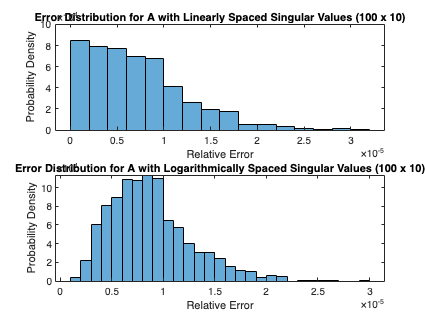

% Define matrix dimensions
m = 100; % Number of rows
n = 10;  % Number of columns
num_trials = 1000;  % Number of trials for different noise vectors

% Generate random matrices U and V
U = randn(m, m);  % U is now m x m
V = randn(n, n);  % V is n x n

% Perform QR factorization to get orthogonal matrices
[U, ~] = qr(U);
[V, ~] = qr(V);

% Create Σ matrices: one with linear spacing, one with logarithmic spacing
sigma_linear = linspace(100, 1, n);         % Singular values spaced linearly from 100 to 1
sigma_log = logspace(log10(100), log10(1), n);  % Singular values spaced logarithmically from 100 to 1

% Create diagonal Σ matrices
Sigma_linear = diag(sigma_linear);  % Diagonal matrix with size n x n
Sigma_log = diag(sigma_log);        % Diagonal matrix with size n x n

% Construct matrices A_linear and A_log (now m x n)
A_linear = U(:, 1:n) * Sigma_linear * V';  % Matrix with linearly spaced singular values
A_log = U(:, 1:n) * Sigma_log * V';        % Matrix with logarithmically spaced singular values

% Create a random b vector (size m x 1)
b = randn(m, 1);

% Solve Ax = b in the least-squares sense for both A_linear and A_log
x_linear = A_linear \ b;
x_log = A_log \ b;

% Initialize arrays to store the errors
errors_linear = zeros(num_trials, 1);
errors_log = zeros(num_trials, 1);

% Loop through multiple trials to compute error distribution
for i = 1:num_trials
    % Generate a small epsilon (norm is 1e-6 smaller than norm(b))
    epsilon = 1e-6 * norm(b) * randn(m, 1);
    b_epsilon = b + epsilon;
    
    % Solve for x using b + epsilon in the least-squares sense
    x_linear_epsilon = A_linear \ b_epsilon;
    x_log_epsilon = A_log \ b_epsilon;
    
    % Compute relative error for each matrix
    errors_linear(i) = norm(x_linear - x_linear_epsilon) / norm(x_linear);
    errors_log(i) = norm(x_log - x_log_epsilon) / norm(x_log);
end

% Plot histograms of the error distributions
figure;
subplot(2,1,1);
histogram(errors_linear, 'Normalization', 'pdf');
title('Error Distribution for A with Linearly Spaced Singular Values (100 x 10)');
xlabel('Relative Error');
ylabel('Probability Density');

subplot(2,1,2);
histogram(errors_log, 'Normalization', 'pdf');
title('Error Distribution for A with Logarithmically Spaced Singular Values (100 x 10)');
xlabel('Relative Error');
ylabel('Probability Density');